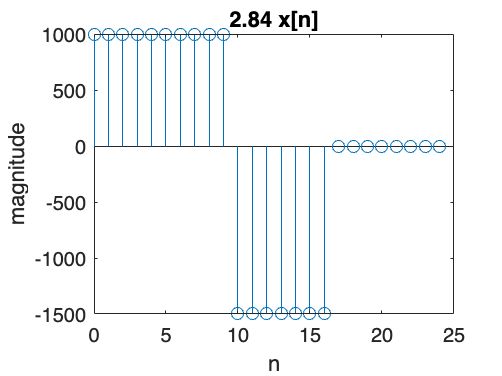

%2.84
x=[1000,1000,1000,1000,1000,1000,1000,1000,1000,1000,-1500,-1500,-1500,-1500,-1500,-1500,-1500,zeros(1,9)];
h=(1.08).^(0:24);
y=conv(x,h); 


stem(0:24,x(1:25))
title('2.84 x[n]')
xlabel('n');
ylabel('magnitude');

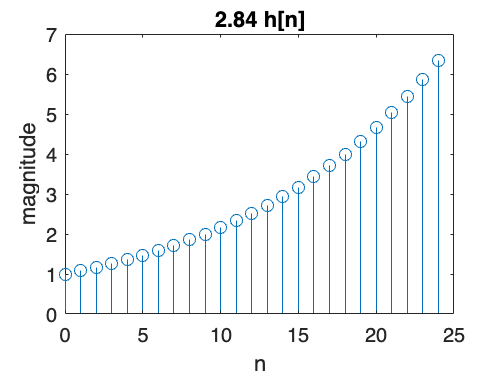


stem(0:24,h(1:25))
title('2.84 h[n]')
xlabel('n');
ylabel('magnitude');

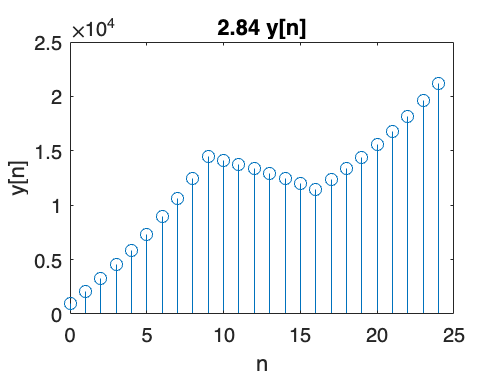


stem(0:24,y(1:25)); 
title('2.84 y[n]')
xlabel('n'); 
ylabel('y[n]');

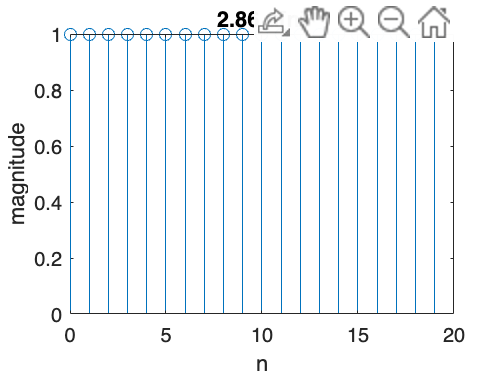

%2.86
h1=[0.25, 0.25, 0.25, 0.25, zeros(1,17) ];
h2=[1/4, -1/4, 1/4, -1/4,zeros(1,17) ];
u=ones(1,20);
s1=conv(h1,x);
s2=conv(h2,x);


stem(0:19,u(1:20))
title('2.86 u[n]')
xlabel('n');
ylabel('magnitude');

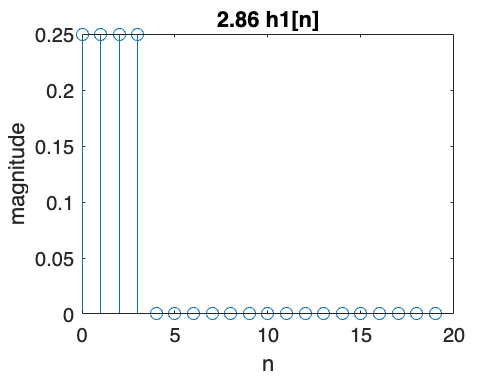


stem(0:19,h1(1:20))
title('2.86 h1[n]')
xlabel('n');
ylabel('magnitude');

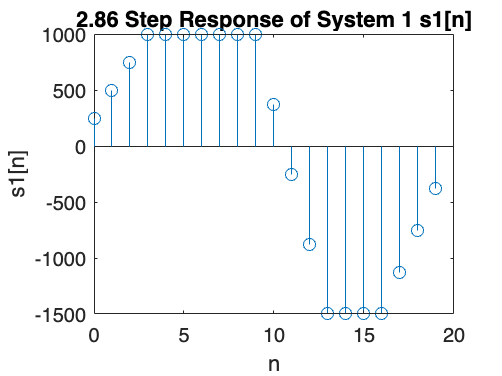


stem(0:19,s1(1:20)); 
title('2.86 Step Response of System 1 s1[n]')
xlabel('n'); 
ylabel('s1[n]');

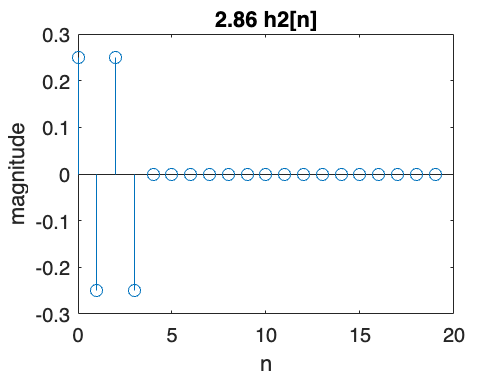


stem(0:19,h2(1:20))
title('2.86 h2[n]')
xlabel('n');
ylabel('magnitude');

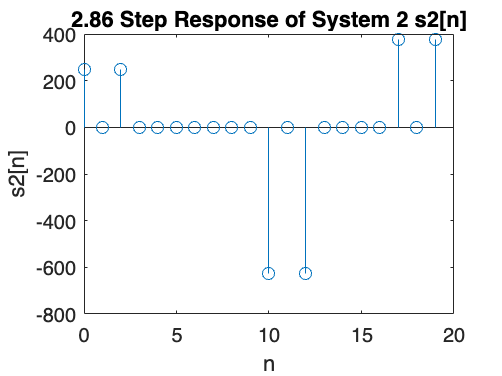


stem(0:19,s2(1:20)); 
title('2.86 Step Response of System 2 s2[n]')
xlabel('n'); 
ylabel('s2[n]');

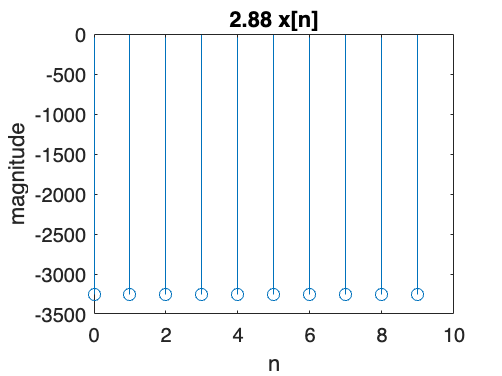

%2.88
a=[1,-1.1];
b=1;
x=[-3254.91,-3254.91,-3254.91,-3254.91,-3254.91,-3254.91,-3254.91,-3254.91,-3254.91,-3254.91];
zi=filtic(b,a,20000);
y=filter(b,a,x,zi);
c=[-1,0,1,2,3,4,5,6,7,8,9];%y[n]橫座標
d=[20000,y(1:10)];%輸出y[-1]=20000和y[n]前十個數值 

stem(0:9,x(1:10)); 
title('2.88 x[n]')
xlabel('n'); 
ylabel('magnitude');

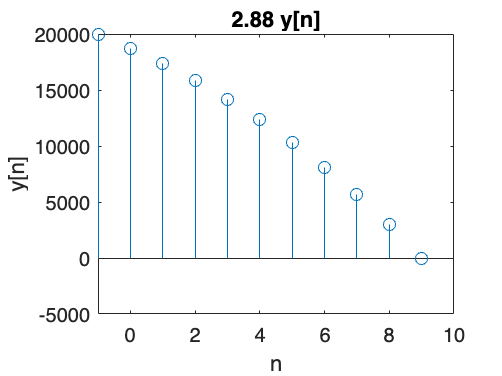



stem(c,d); 
title('2.88 y[n]')
xlabel('n'); 
ylabel('y[n]');

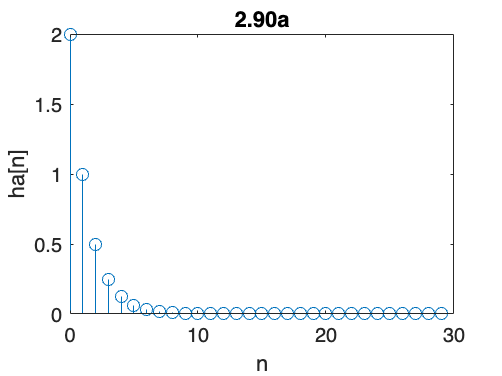

%2.90
%a
a=[1,-0.5];
b=2;
[h,t]=impz(b,a,30);

stem(t(1:30),h(1:30)); 
title('2.90a')
xlabel('n'); 
ylabel('ha[n]');

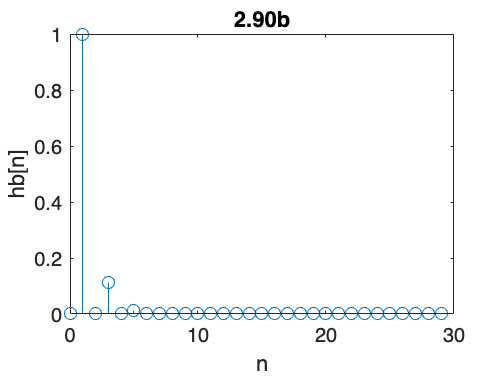

%2.90
%b
a=[1,0,-1/9];
b=[0,1];
[h,t]=impz(b,a,30);

stem(t(1:30),h(1:30)); 
title('2.90b')
xlabel('n'); 
ylabel('hb[n]');

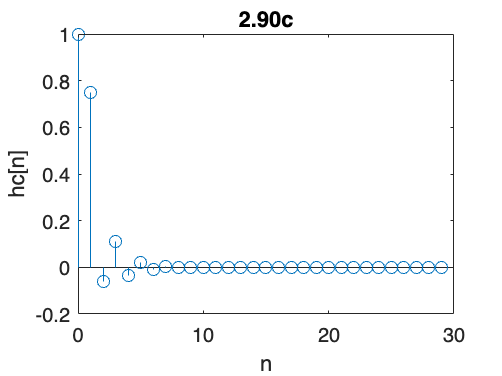

%2.90
%c
a=[1,1/4,-1/8];
b=[1,1];
[h,t]=impz(b,a,30);

stem(t(1:30),h(1:30)); 
title('2.90c')
xlabel('n'); 
ylabel('hc[n]');

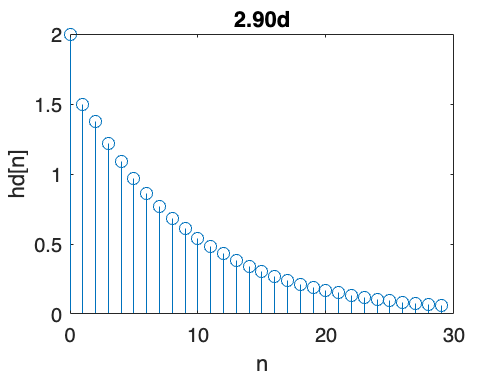

%2.90
%d
a=[1,-3/4,-1/8];
b=2;
[h,t]=impz(b,a,30);

stem(t(1:30),h(1:30)); 
title('2.90d')
xlabel('n'); 
ylabel('hd[n]');

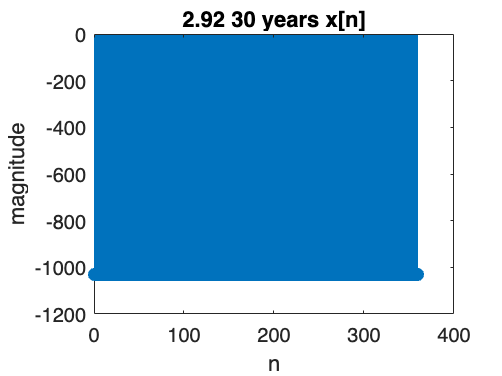

%2.92(30 years)
a=[1,-1.01];
b=1;
p=(101000*(1.01)^359)/((101)*(1.01)^359-100);
x=repmat(-p,360);

zi=filtic(b,a,100000);
y=filter(b,a,x,zi);

stem(0:359,x(1:360)); 
title('2.92 30 years x[n]')
xlabel('n'); 
ylabel('magnitude');

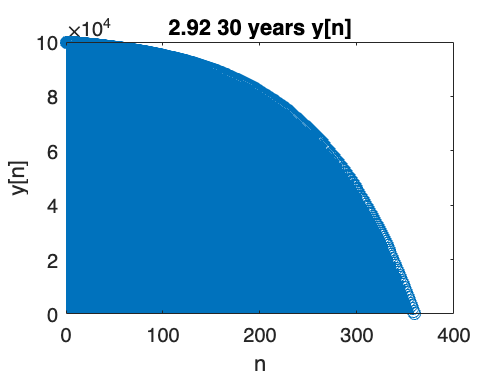


stem(0:359,y(1:360)); 
title('2.92 30 years y[n]')
xlabel('n'); 
ylabel('y[n]');

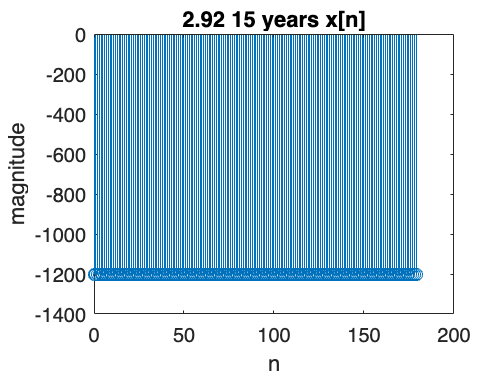

%2.92(15 years)
a=[1,-1.01];
b=1;
p=(101000*(1.01)^179)/((101)*(1.01)^179-100);
x=repmat(-p,180);

zi=filtic(b,a,100000);
y=filter(b,a,x,zi);

stem(0:179,x(1:180)); 
title('2.92 15 years x[n]')
xlabel('n'); 
ylabel('magnitude');

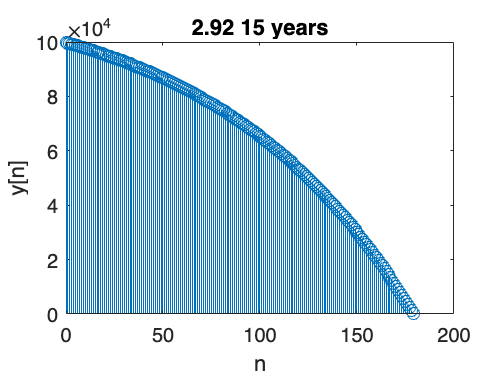


stem(0:179,y(1:180)); 
title('2.92 15 years')
xlabel('n'); 
ylabel('y[n]');